
% main.m
% Find ground state and run a simple time evolution (split-step FFT).
clear; clearvars; close all; clc;

% ---------------- User Parameters ----------------
rspan = [1e-6, 10];                  % radial domain [r0, R]
opts = odeset('RelTol',1e-10,'AbsTol',1e-10,'Events',@asymptotic_event);

nth_state = 1;                       % 1 = ground state
Q_left_init = 0;
Q_right_init = 15;
tol_target = 1e-8;

% Time-evolution / spectral grid parameters
Mx = 256; My = 256;                  % grid resolution
a  = 20;                             % domain [-a,a] x [-a,a]
T  = 10;                             % final time

doTimeEvolution = true;              % set false to skip evolution

% Output folder
results_dir = 'results';
if ~exist(results_dir, 'dir')
    mkdir(results_dir);
end
timestamp = datestr(now, 'yyyymmdd_HHMMSS');

% ---------------- Find Ground State ----------------
fprintf('Finding ground state (nth_state = %d)...\n', nth_state);

Finding ground state (nth_state = 1)...


[r_sol, Q_sol, Q_star, diagnostics] = find_nth_state(nth_state, opts, rspan, Q_left_init, Q_right_init, tol_target);
fprintf('Found Q(0) ≈ %.12g\n', Q_star);

Found Q(0) ≈ 2.20620091819


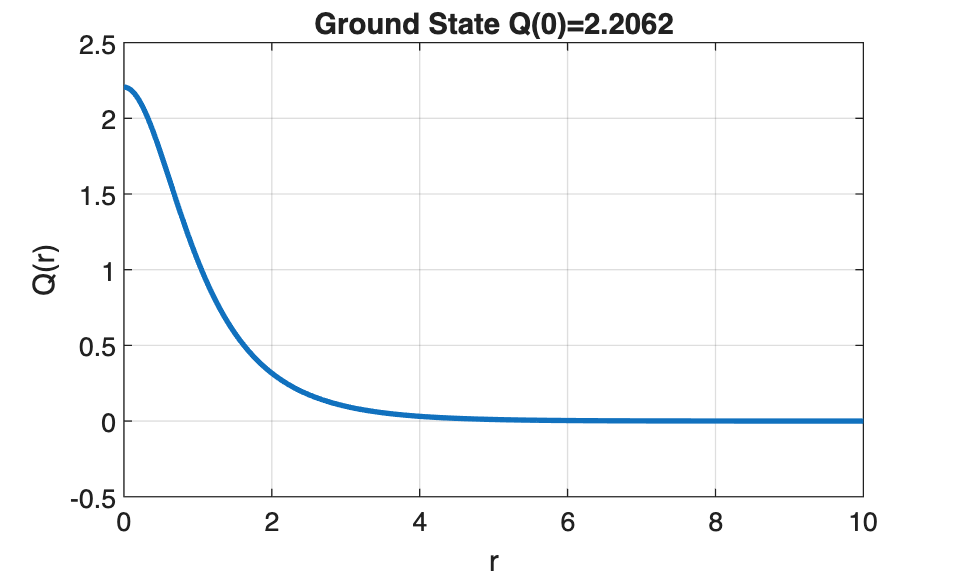


% Save radial solution
save(fullfile(results_dir, sprintf('radial_n%d_%s.mat', nth_state, timestamp)), 'r_sol', 'Q_sol', 'Q_star', 'diagnostics', '-v7.3');

% Plot radial solution
figure('Name','Radial Solution','NumberTitle','off');
plot(r_sol, Q_sol, 'LineWidth', 2);
xlabel('r'); ylabel('Q(r)'); grid on;
title(sprintf('Ground State Q(0)=%.6g', Q_star));
saveas(gcf, fullfile(results_dir, sprintf('radial_plot_n%d_%s.png', nth_state, timestamp)));

Running time evolution to T = 10 ...


t = 0

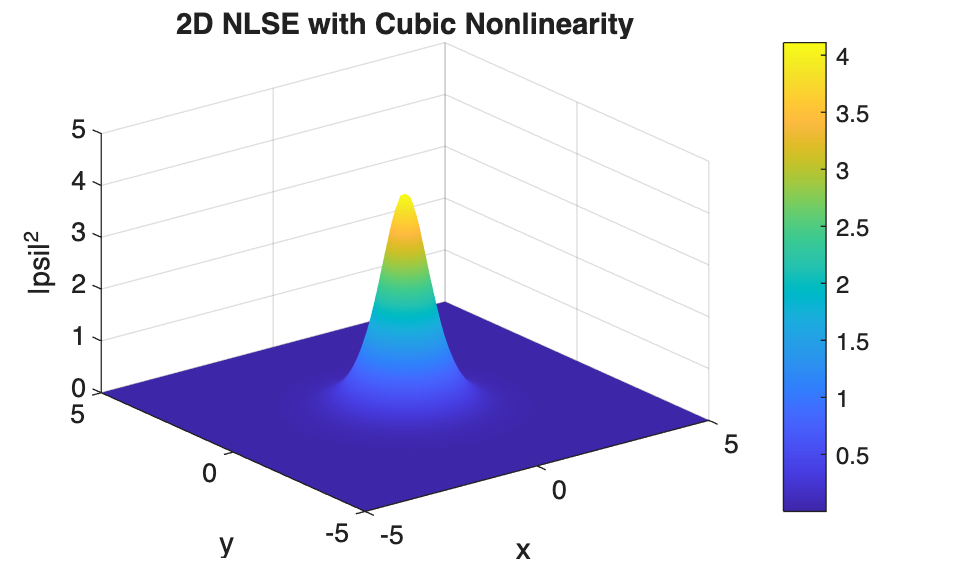


% ---------------- Build 2D Initial Condition ----------------
dx = 2*a / Mx;
dy = 2*a / My;
x = linspace(-a, a-dx, Mx);
y = linspace(-a, a-dy, My);
[X, Y] = meshgrid(x, y);
R_grid = sqrt(X.^2 + Y.^2);

% Interpolate radial solution onto 2D grid (spline; zero outside R)
Q_on_R = interp1(r_sol, Q_sol, R_grid, 'spline', 0);
psi0 = Q_on_R;   % real-valued initial field

% ---------------- Time Evolution (live surf like old.mlx) ----------------
if doTimeEvolution
    fprintf('Running time evolution to T = %.4g ...\n', T);

    % --- Simulation params ---
    Mx = 512;           % grid points in x
    My = 512;           % grid points in y
    a  = 20;            % domain [-a,a] x [-a,a]
    dt = 0.01;
    T  = 3;
    
    dx = 2*a/Mx;
    dy = 2*a/My;
    
    x = linspace(-a, a-dx, Mx);   % x-grid
    y = linspace(-a, a-dy, My);   % y-grid
    [X,Y] = meshgrid(x,y);        % 2D grid
    
    % --- NLSE params ---
    epsilon = -1;
    
    %Interpolation of Numerically Evaluated State
    R_grid = sqrt(X.^2 + Y.^2);
    Q_on_R = interp1(r_sol, Q_sol, R_grid, 'spline', 0);   
    psi = Q_on_R;   
    
    mx = (-Mx/2 : Mx/2-1);         % modes in x
    my = (-My/2 : My/2-1);         % modes in y
    
    kx = (pi/a) * mx;              % wave numbers in x
    ky = (pi/a) * my;              % wave numbers in y
    
    [KX,KY] = meshgrid(kx,ky);     % 2D wave-number grid
    lambda = KX.^2 + KY.^2;        % eigenvalues 
    
    K = exp(-1i * lambda * dt/2);  % half-step kinetic operator
    
    figure
    h = surf(X, Y, abs(psi).^2);
    shading interp            % smoother look (optional)
    colorbar                  % show color scale
    xlabel('x'); ylabel('y'); zlabel('|psi|^2');
    title('2D NLSE with Cubic Nonlinearity');
    xlim([-5,5])
    ylim([-5,5])
    axis manual         
    t = 0
     %Time Evolution 
    while t < T
    
        % Fourier transform 
        psi_hat = fftshift(fft2(psi));
    
        % 1st half-step kinetic
        psi_hat = K .* psi_hat;
    
        psi = ifft2(ifftshift(psi_hat));
    
        % Nonlinear step
        psi = exp(-1i*epsilon*dt*abs(psi).^2) .* psi;
    
        psi_hat = fftshift(fft2(psi));
    
        % 2nd half-step 
        psi_hat = K .* psi_hat;
    
        psi = ifft2(ifftshift(psi_hat));
    
        t = t + dt;
        set(h, 'ZData', abs(psi).^2);
        drawnow;
    end
end


fprintf('Main run complete. Results saved to: %s\n', results_dir);

Main run complete. Results saved to: results
